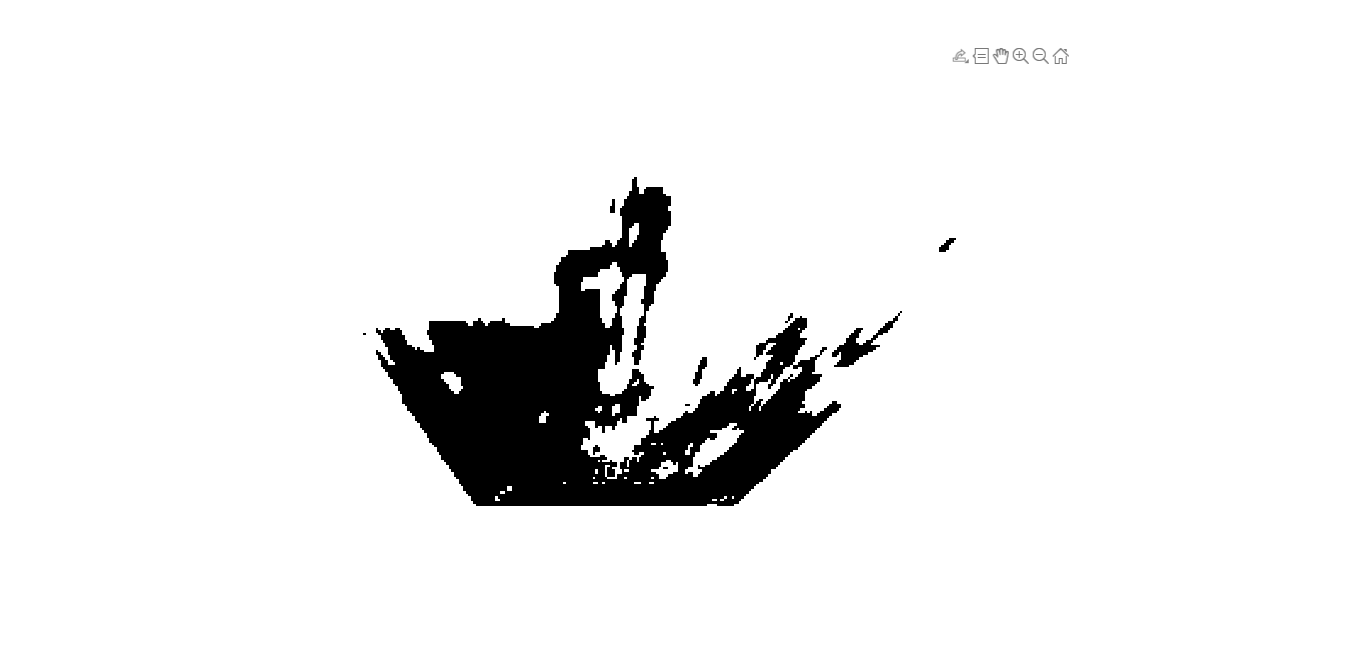

%map = false(10); %Input map parameters
%map (1:5, 6) = true; %Obstacle Declaration
%map=imread("top_view.png");

load("J.mat");
J=imresize(J,[180 320]);
map=J;

%load("C.mat");
%C=imresize(C,0.25);
%map = C=="Road";

map = imcomplement(map);
imshow(map);
%[x,y]=ginput(2);
[p1,p2] = getpts;

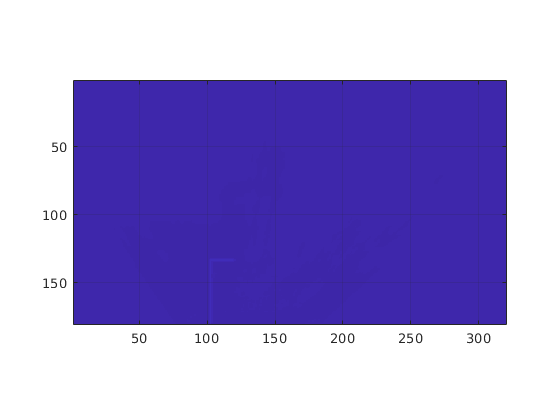

p1=round(p1);
p2=round(p2);
start_coords = [p1(1), p1(2)]; %Starting coordinates
dest_coords  = [p2(1), p2(2)]; %Destination Coordinates
drawMapEveryTime = false; %Display Outputs
[route, numExpanded,path] = AStarGrid(map, start_coords, dest_coords,drawMapEveryTime); %Implementation

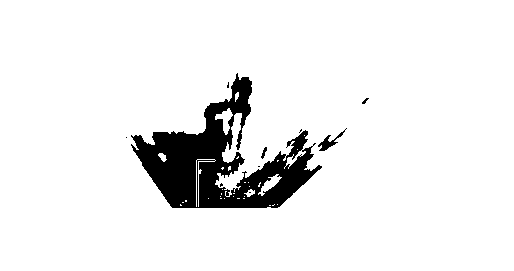

path(path~=4)=0;
path(path==4)=1;
%map=imcomplement(map);
kk=or(path,map);
imshow(kk);

function [route,numExpanded,path] = AStarGrid (input_map, start_coords, dest_coords,drawMapEveryTime)
% Run A* algorithm on a grid.
% Inputs : 
%   input_map : a logical array where the freespace cells are false or 0 and
%   the obstacles are true or 1
%   start_coords and dest_coords : Coordinates of the start and end cell
%   respectively, the first entry is the row and the second the column.
% Output :
%    route : An array containing the linear indices of the cells along the
%    shortest route from start to dest or an empty array if there is no
%    route. This is a single dimensional vector
%    numExpanded: Remember to also return the total number of nodes
%    expanded during your search. Do not count the goal node as an expanded node. 

% set up color map for display
% 1 - white - clear cell
% 2 - black - obstacle
% 3 - red = visited
% 4 - blue  - on list
% 5 - green - start
% 6 - yellow - destination

%{
cmap = [1 1 1; ...
    0 0 0; ...
    1 0 0; ...
    0 0 1; ...
    0 1 0; ...
    1 1 0; ...
    0.5 0.5 0.5];

colormap(cmap);
%}

[nrows, ncols] = size(input_map);

% map - a table that keeps track of the state of each grid cell
map = zeros(nrows,ncols);

map(~input_map) = 1;   % Mark free cells
map(input_map)  = 2;   % Mark obstacle cells

% Generate linear indices of start and dest nodes
start_node = sub2ind(size(map), start_coords(1), start_coords(2));
dest_node  = sub2ind(size(map), dest_coords(1),  dest_coords(2));
start_node=round(start_node);
dest_node=round(dest_node);
map(start_node) = 5;
map(dest_node)  = 6;

% meshgrid will `replicate grid vectors' nrows and ncols to produce
% a full grid
% type `help meshgrid' in the Matlab command prompt for more information
parent = zeros(nrows,ncols);

% 
[X, Y] = meshgrid (1:ncols, 1:nrows);

xd = dest_coords(1);
yd = dest_coords(2);

% Evaluate Heuristic function, H, for each grid cell
% Manhattan distance
H = abs(X - xd) + abs(Y - yd);
H = H';
% Initialize cost arrays
f = Inf(nrows,ncols);
g = Inf(nrows,ncols);

g(start_node) = 0;
f(start_node) = H(start_node);

% keep track of the number of nodes that are expanded
numExpanded = 0;

% Main Loop

while true
    
    % Draw current map
    map(start_node) = 5;
    map(dest_node) = 6;
    
    % make drawMapEveryTime = true if you want to see how the 
    % nodes are expanded on the grid. 
    if (drawMapEveryTime)
        image(1.5, 1.5, map);
        grid on;
        axis image;
        drawnow;
    end
    
    % Find the node with the minimum f value
    [min_f, current] = min(f(:));
    
    if ((current == dest_node) || isinf(min_f))
        break;
    end;
    
    % Update input_map
    map(current) = 3;
    f(current) = Inf; % remove this node from further consideration
    
    % Compute row, column coordinates of current node
    [i, j] = ind2sub(size(f), current);
    
    % *********************************************************************
    % ALL YOUR CODE BETWEEN THESE LINES OF STARS
    % Visit all of the neighbors around the current node and update the
    % entries in the map, f, g and parent arrays
    %
    
    x=0;
    y=0;
    if (i>1 && i<=nrows) 
        x = i-1;
        y = j;
        if (map(x,y)~=2 && map(x,y)~=3 && map(x,y)~=5)
            if g(x,y) > (g(i,j) + (H(x,y)-H(i,j)))
                g(x,y) = g(i,j) + (H(x,y)-H(i,j));
                f(x,y) = g(x,y) + H(x,y);
                map(x,y) = 4;
                parent(x,y) = current;
            end
        end
    end
    if (i>=1 && i<nrows) 
        x = i+1;
        y = j;
        if (map(x,y)~=2 && map(x,y)~=3 && map(x,y)~=5)
            if g(x,y) > (g(i,j) + (H(x,y)-H(i,j)))
                g(x,y) = g(i,j) + (H(x,y)-H(i,j));
                f(x,y) = g(x,y) + H(x,y);
                map(x,y) = 4;
                parent(x,y) = current;
            end
        end
    end
    if (j>1 && j<=ncols) 
        y = j-1;
        x = i;
         if (map(x,y)~=2 && map(x,y)~=3 && map(x,y)~=5)
            if g(x,y) > (g(i,j) + (H(x,y)-H(i,j)))
                g(x,y) = g(i,j) + (H(x,y)-H(i,j));
                f(x,y) = g(x,y) + H(x,y);
                map(x,y) = 4;
                parent(x,y) = current;
            end
         end
    end
    if (j>=1 && j<ncols) 
        y =j+1;
        x = i;
         if (map(x,y)~=2 && map(x,y)~=3 && map(x,y)~=5)
            if g(x,y) > (g(i,j) + (H(x,y)-H(i,j)))
                g(x,y) = g(i,j) + (H(x,y)-H(i,j));
                f(x,y) = g(x,y) + H(x,y);
                map(x,y) = 4;
                parent(x,y) = current;
            end
         end
    end
    
    numExpanded = numExpanded + 1;
    
    f(current) = Inf;
    
    
    
    %*********************************************************************
    
    
end

%% Construct route from start to dest by following the parent links
if (isinf(f(dest_node)))
    route = [];
else
    route = [dest_node];
    
    while (parent(route(1)) ~= 0)
        route = [parent(route(1)), route];
    end

    % Snippet of code used to visualize the map and the path
    for k = 2:length(route) - 1        
        map(route(k)) = 7;
        pause(0.1);
        image(1.5, 1.5, map);
        grid on;
        axis image;
    end
end
path=map;
end
